clc
clear
close all

## input reaction time in mili seconds

y = [607, 583, 521, 494, 369, 782, 570, 678, 467, 620, 425, 395, 346, 361, ...
    310, 300, 382, 294, 315, 323, 421, 339, 398, 328, 335, 291, 329, 310, ...
    294, 321, 286, 349, 279, 268, 293, 310, 259, 241, 243, 272, 247, 275,...
    220, 245, 268, 357, 273, 301, 322, 276, 401, 368, 149, 507, 411, 362,...
    358, 355, 362, 324, 332, 268, 259, 274, 248, 254, 242, 286, 276, 237,...
    259, 251, 239, 247, 260, 237, 206, 242, 361, 267, 245, 331, 357, 284,...
    263, 244, 317, 225, 254, 253, 251, 314, 239, 248, 250, 200, 256, 233,...
    427, 391, 331, 395, 337, 392, 352, 381, 330, 368, 381, 316, 335, 316,...
    302, 375, 361, 330, 351, 186, 221, 278, 244, 218, 126, 269, 238, 194,...
    384, 154, 555, 387, 317, 365, 357, 390, 320, 316, 297, 354, 266, 279,...
    327, 285, 258, 267, 226, 237, 264, 510, 490, 458, 425, 522, 927, 555,...
    550, 516, 548, 560, 545, 633, 496, 498, 223, 222, 309, 244, 207, 258,...
    255, 281, 258, 226, 257, 263, 266, 238, 249, 340, 247, 216, 241, 239,...
    226, 273, 235, 251, 290, 473, 416, 451, 475, 406, 349, 401, 334, 446,...
    401, 252, 266, 210, 228, 250, 265, 236, 289, 244, 327, 274, 223, 327,...
    307, 338, 345, 381, 369, 445, 296, 303, 326, 321, 309, 307, 319, 288,...
    299, 284, 278, 310, 282, 275, 372, 295, 306, 303, 285, 316, 294, 284,...
    324, 264, 278, 369, 254, 306, 237, 439, 287, 285, 261, 299, 311, 265,...
    292, 282, 271, 268, 270, 259, 269, 249, 261, 425, 291, 291, 441, 222,...
    347, 244, 232, 272, 264, 190, 219, 317, 232, 256, 185, 210, 213, 202,...
    226, 250, 238, 252, 233, 221, 220, 287, 267, 264, 273, 304, 294, 236,...
    200, 219, 276, 287, 365, 438, 420, 396, 359, 405, 397, 383, 360, 387,...
    429, 358, 459, 371, 368, 452, 358, 371];

## user indices

ind = [1, 1, 1, 1, 1, 2, 2, 2, 2, 2, 3, 3, 3, 3, 3, 3, 3, 3, 3, 4, 5, 5,...
    5, 5, 5, 5, 5, 5, 5, 5, 5, 5, 5, 5, 5, 5, 6, 6, 6, 6, 6, 6, 6, 6, 6,...
    7, 7, 7, 7, 7, 8, 8, 8, 8, 8, 9, 9, 9, 9, 9, 10, 10, 10, 10, 10, 10,...
    10, 10, 10, 10, 10, 10, 10, 10, 10, 10, 10, 10, 11, 11, 11, 11, 11,...
    11, 11, 11, 11, 11, 11, 11, 11, 11, 11, 11, 11, 11, 11, 11, 12, 12,...
    12, 12, 12, 12, 12, 12, 12, 12, 12, 12, 12, 12, 12, 12, 12, 12, 12,...
    12, 13, 13, 13, 13, 13, 13, 13, 13, 13, 13, 14, 14, 14, 14, 14, 14,...
    14, 14, 14, 14, 14, 14, 14, 15, 15, 15, 15, 15, 15, 16, 16, 16, 16,...
    16, 17, 17, 17, 17, 17, 18, 18, 18, 18, 18, 19, 19, 19, 19, 19, 20,...
    20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20, 20,...
    20, 20, 21, 21, 21, 21, 21, 21, 21, 21, 21, 21, 22, 22, 22, 22, 22,...
    22, 22, 22, 22, 22, 22, 22, 23, 23, 23, 23, 23, 23, 23, 23, 23, 23,...
    24, 24, 24, 24, 24, 24, 24, 24, 24, 24, 24, 24, 24, 24, 24, 24, 24,...
    24, 24, 24, 25, 25, 25, 25, 25, 25, 25, 25, 25, 25, 25, 25, 25, 26,...
    26, 26, 26, 26, 27, 27, 27, 27, 27, 28, 28, 28, 28, 28, 28, 28, 28,...
    28, 29, 29, 29, 29, 29, 29, 29, 29, 29, 29, 30, 30, 30, 30, 30, 30,...
    31, 31, 31, 31, 31, 32, 32, 32, 32, 32, 33, 34, 34, 34, 34, 34, 34,...
    34, 34, 34, 34, 34, 34, 34, 34, 34, 34, 34, 34];

## whether the user is chaile (1) or adult (0)

child_i = [1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0,...
    0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, ...
    0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, ...
    0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, ...
    0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, ...
    0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 1, ...
    1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 1, ...
    1, 1, 1, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, ...
    0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, ...
    0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 1, 1, 1, 1, ...
    1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, ...
    0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, ...
    1, 1, 1, 1, 1, 1, 1, 1, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, ...
    0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, ...
    0, 0, 0, 0, 0, 0, 0, 0, 0, 0];

child = [1, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 1, 1, 1, 1, 0, 0, ...
    0, 0, 1, 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0];

## Getting each theta_j set in logrithmic form

l = 0;
for i =1:max(ind)
    logy{i} = log(y(1+l:l+length(ind(ind==i))));
    l = l+length(ind(ind==i));
end

for i=1:max(ind)
    theta(i) = (mean(logy{i}));
end

## Standardization of data

zlogy = (log(y)-mean(log(y)))/std(log(y));

## slice sampling

beta0 = ones(max(ind)+4,1);
nsamples = 10000;

% slice sampler for assignment 6
SL_SMAPLE = slicesample(beta0,nsamples,'logpdf',@(beta) ...
    log_post(beta,zlogy,ind,child));

% slice sampler for assignment 5
SL_SMAPLE_5 = slicesample(beta0(1:end-1),nsamples,'logpdf',@(beta_5) ...
    log_post_5(beta_5,zlogy,ind));
% ========================================================================

## Task 1

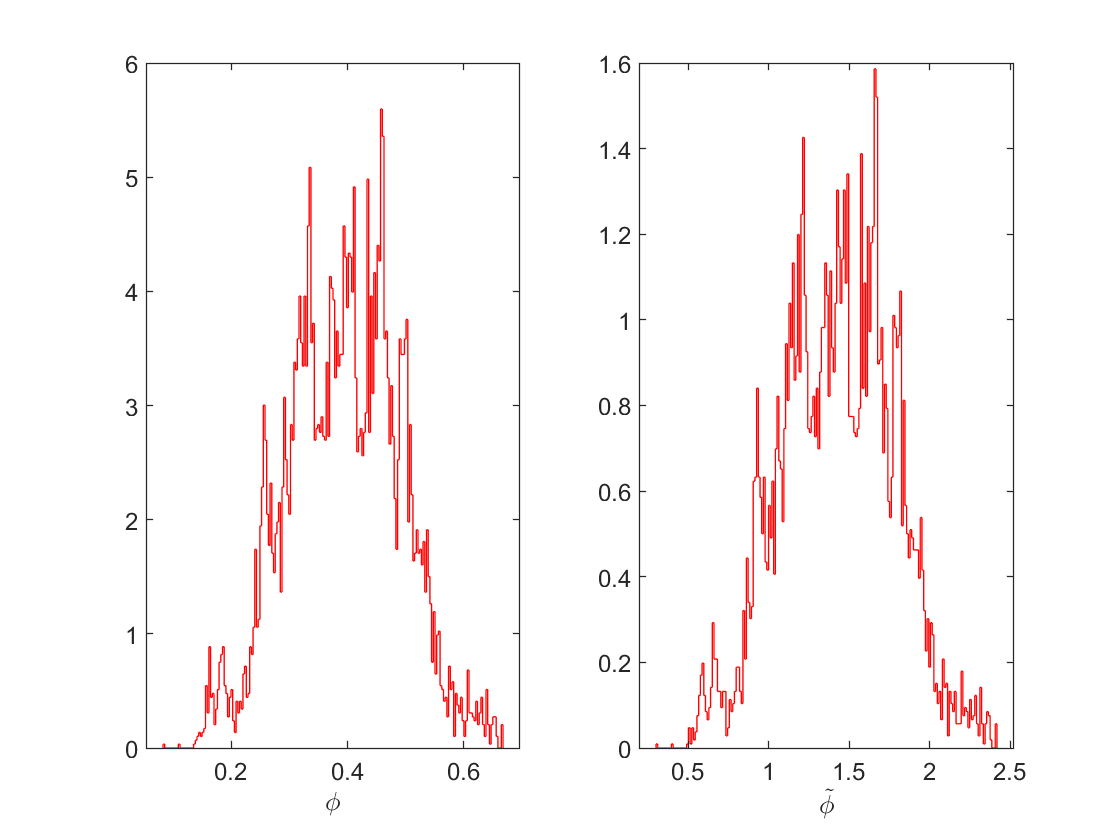

phi_n = SL_SMAPLE(:,38);    % normalized phi
phi = std(log(y))*phi_n;    % original phi 

subplot(1,2,1);
h_phi=histogram(phi,200,'normalization','pdf','DisplayStyle', ...
    'stairs','EdgeColor','r');
xlabel('$\phi$', 'Interpreter', 'LaTeX');

subplot(1,2,2);
h_phi_n = histogram(phi_n,200,'normalization','pdf','DisplayStyle', ...
    'stairs','EdgeColor','r');
xlabel('$$\tilde{\phi}$$', 'Interpreter', 'LaTeX');


% since the results of \phi exclude 0, we can say the groups are different.

## Task 2

tau for assignment 6

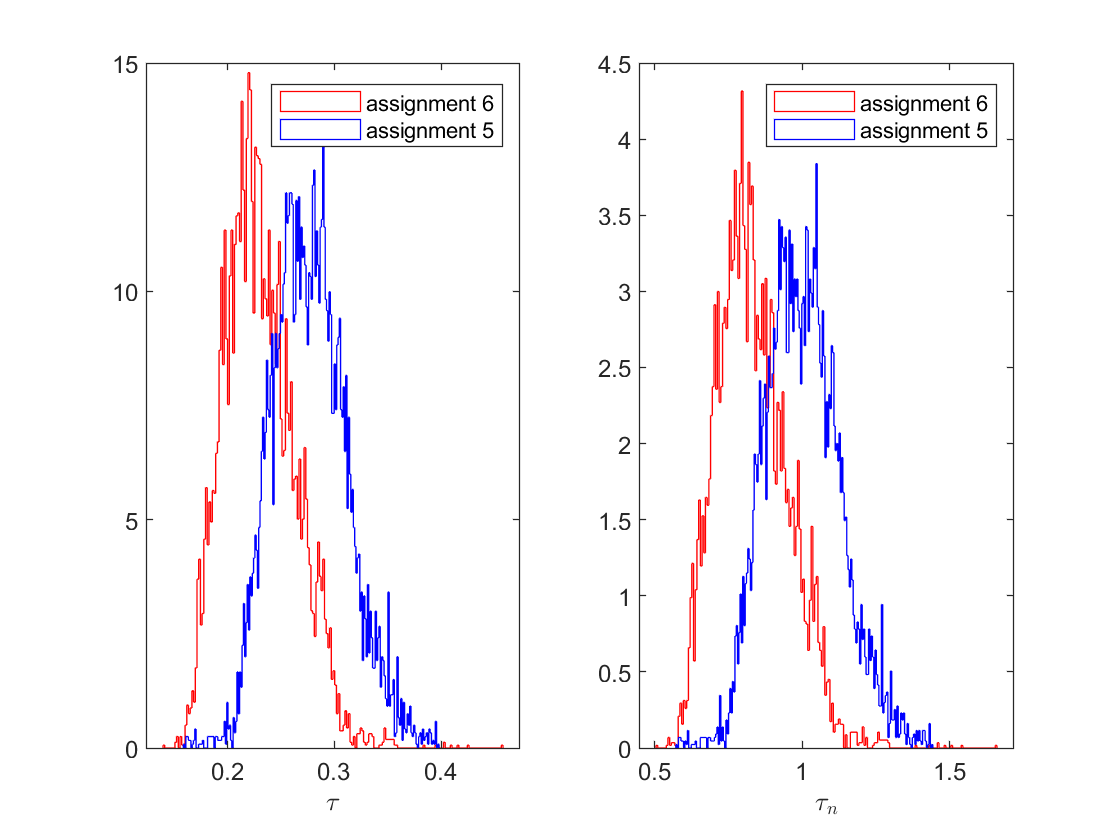

tau_n  = SL_SMAPLE(:,end-2);
tau = std(log(y))*tau_n;

% tau for assignment 5
tau_n_5  = SL_SMAPLE_5(:,end-1);
tau_5 = std(log(y))*tau_n_5;


figure(2)
subplot(1,2,1);

h=histogram(tau,200,'normalization','pdf','DisplayStyle','stairs', ...
    'EdgeColor','r');
hold on
h=histogram(tau_5,200,'normalization','pdf','DisplayStyle','stairs', ...
    'EdgeColor','b');
xlabel('$\tau$', 'Interpreter', 'LaTeX')
legend({'assignment 6','assignment 5'})
subplot(1,2,2);
h=histogram(tau_n,200,'normalization','pdf','DisplayStyle','stairs' ...
    ,'EdgeColor','r');
hold on
h=histogram(tau_n_5,200,'normalization','pdf','DisplayStyle','stairs', ...
    'EdgeColor','b');
xlabel('$\tau_n$', 'Interpreter', 'LaTeX')
legend({'assignment 6','assignment 5'})


% \tau in assignment 6 is shifter toward 0, which can be related to adding
% a prior (more knowledge) on the data (kids and adults)

## Task 3

obtaining mean in the original form

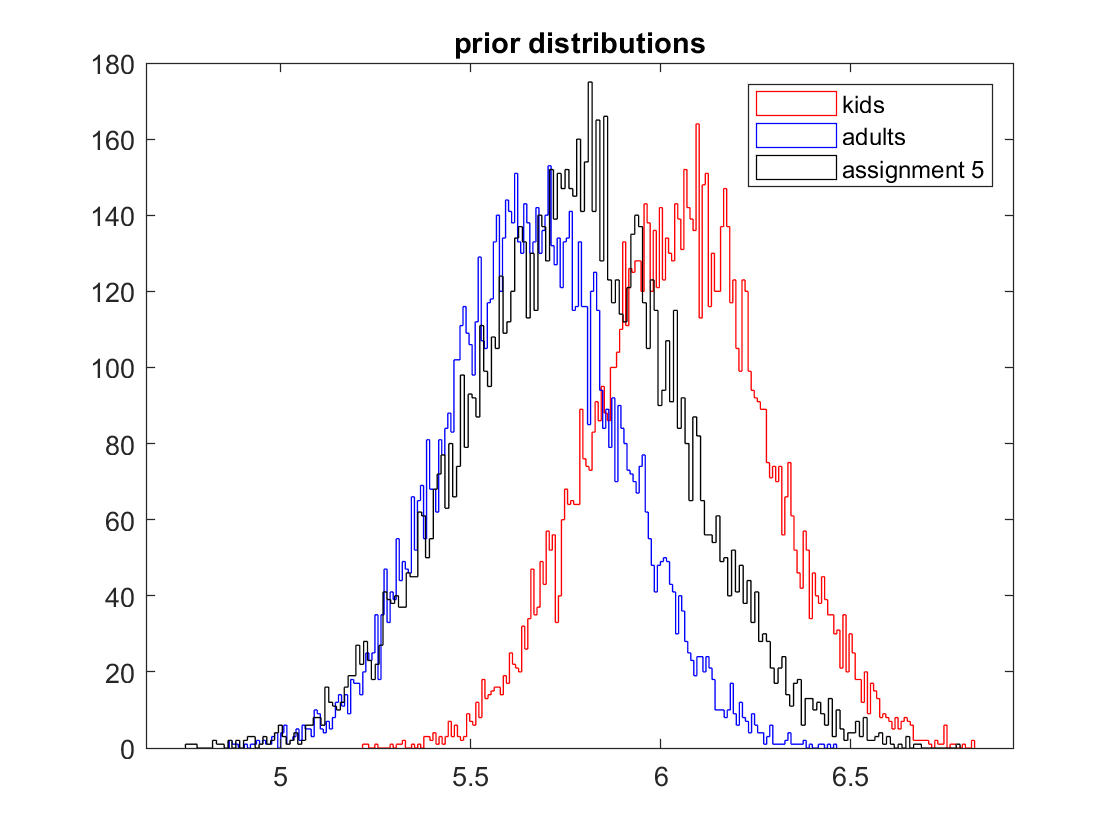

mu = std(log(y))*SL_SMAPLE(:,end-3)+mean(log(y));
% constructing prior using theta = mu+phi + tau.rand
prior_child = (mean(mu +phi)+mean(tau).*randn(nsamples,1));
% constructing prior using theta = mu+0*phi + tau.rand  (adults, phi =0)
prior_adult=(mean(mu)+mean(tau).*randn(nsamples,1)); 

% ploting histograms
figure(3)
h1 = histogram(prior_child,200,'DisplayStyle','stairs','EdgeColor','r');
title("prior distributions")
hold on;

h2 = histogram(prior_adult,200,'DisplayStyle','stairs','EdgeColor','b');

% ploting the result from assignment 5
mu_5= std(log(y))*SL_SMAPLE_5(:,end-2)+mean(log(y));
prior_assignment_5=mean(mu_5)+mean(tau_5).*randn(nsamples,1);

h3 = histogram(prior_assignment_5,200,'DisplayStyle','stairs', ...
    'EdgeColor','k');
legend({'kids','adults','assignment 5'})

% prior distribution adjusted basedo n our beliefs, kids have higher mean
% in the prior, since in assignemnt 5 we did not categorize the data it is
% logical that its prior lies between these two in assignment 6.

## Task 4

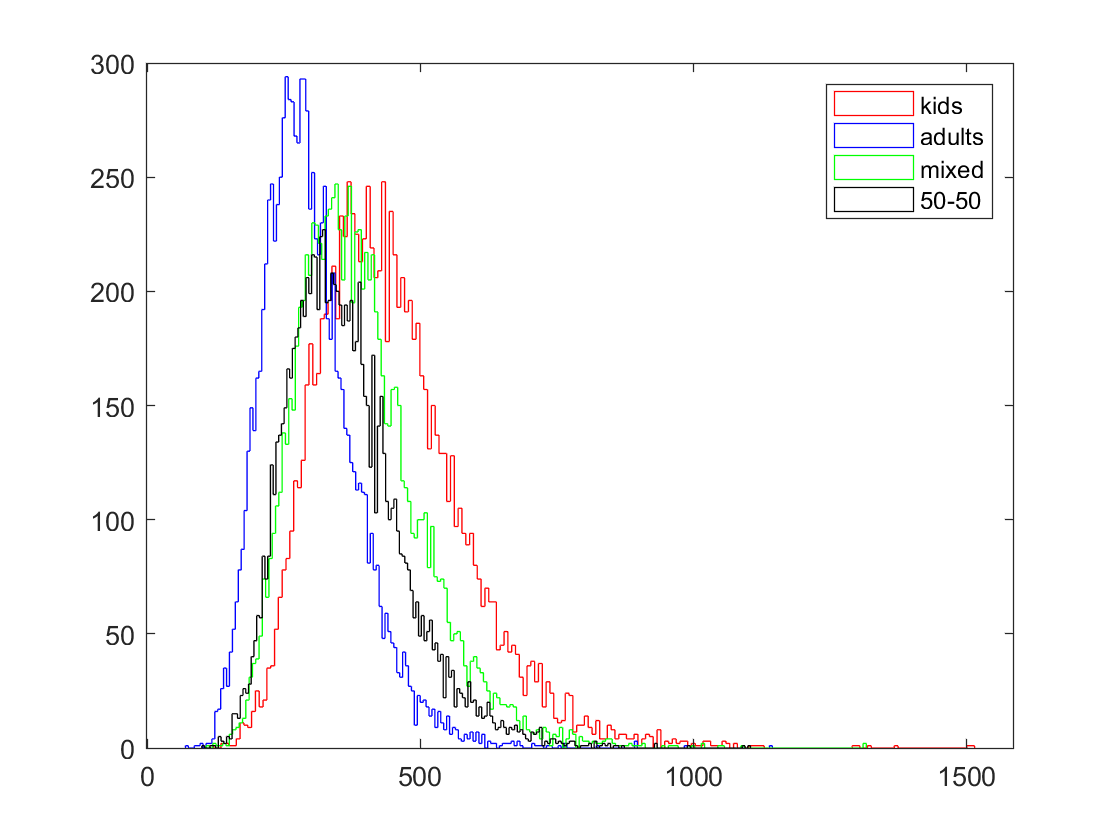

NoOfKids = nnz(child);
NoOfAdults = length(child) - NoOfKids;

figure(4);
mu  = SL_SMAPLE(:,end-3);
tau  = SL_SMAPLE(:,end-2);
sigma = SL_SMAPLE(:,end-1);

% knowing the case is a kid phi =1
knowing_child =  mu + phi_n + tau.*randn(nsamples,1)+sigma.*randn(nsamples,1);
knowing_child = exp(std(log(y))*knowing_child+ mean(log(y)));
h1=histogram(knowing_child,200,'DisplayStyle','stairs','EdgeColor','r');
hold on

knowing_adult = mu + tau.*randn(nsamples,1)+sigma.*randn(nsamples,1);
knowing_adult = exp(std(log(y))* knowing_adult + mean(log(y)));
h2=histogram(knowing_adult,200,'DisplayStyle','stairs','EdgeColor','b');

% plotting mixed histogram of kids/adults = real ratio as given
child_unkown=betarnd(NoOfAdults+1,NoOfKids+1);
zlogy_childunknown= mu+ phi_n.*child_unkown+tau.*randn(nsamples,1)+sigma.*randn(nsamples,1);
logy_childunknown_unscaled=std(log(y))*zlogy_childunknown+mean(log(y));
y_child_unknown=exp(logy_childunknown_unscaled);
h3=histogram(y_child_unknown,200,'DisplayStyle','stairs','EdgeColor','g');

% plotting mixed histogram of kids/adults = 0.5
child_unkown=betarnd(0.5*(NoOfAdults+NoOfKids)+1, ...
    0.5*(NoOfAdults+NoOfKids)+1);
zlogy_childunknown= mu+ phi_n.*child_unkown+tau.*randn(nsamples,1)+sigma.*randn(nsamples,1);
logy_childunknown_unscaled=std(log(y))*zlogy_childunknown+mean(log(y));
y_child_unknown=exp(logy_childunknown_unscaled);
h3=histogram(y_child_unknown,200,'DisplayStyle','stairs','EdgeColor','k');
legend({'kids','adults','mixed'})
legend({'kids','adults','mixed','50-50'})


% we sampled the data from a beta distribution first: Beta(N-z+a,z+b),
% a=b=1
%then constructed the posterior from the priors and liklehood. 
%==========================================================================

## Constructing posterior distribution

function lpost=log_post(beta,zlogy,ind,child)
theta = beta(1:end-4);
mu = beta(end-3);
tau = beta(end-2);
sigma = beta(end-1);
phi = beta(end);

lpost = log_liklihood(beta,zlogy,ind) + ...
    log_piror_theta(beta,child)+log_prior_mu(beta) + ...
    log_prior_tau(beta)+log_prior_sigma(beta);
end

## Setting up prior distributions

function lpmu = log_prior_mu(beta)  % logrithmic prior for mu
mu = beta(end-3);
lpmu = 0;
end

function lptau =log_prior_tau(beta)
tau = beta(end-2);
if tau >0;lptau = 0;else;lptau = -inf;end
end

function lpsigma = log_prior_sigma(beta)
sigma = beta(end-1);
if sigma >0;lpsigma = 0;else;lpsigma = -inf;end
end

## Construction logrithmic prior for theta

function lpt= log_piror_theta(beta,child)
theta = beta(1:end-4);
mu = beta(end-3);
tau = beta(end-2);
sigma = beta(end-1);
phi = beta(end);
lpt=0;
for i = 1: length(theta)
    lpt = lpt+(-log(tau)-0.5*((theta(i)-(mu+phi*child(i)))/tau)^2);
end
end

## Constructing likelihood distribution

function ll=log_liklihood(beta,zlogy,ind)
theta = beta(1:end-4);
sigma = beta(end-1);
theta=theta(:);

ll=0;
for i = 1: length(zlogy)
    ll = ll+(zlogy(i)-theta(ind(i))).^2;
end

ll=-length(zlogy)*log(sigma)-0.5*ll/sigma^2;
end

## ========================================================================

## Constructing posterior distribution for assignement 5:

function lpost_5=log_post_5(beta_5,zlogy,ind)
theta_5 = beta_5(1:end-3);
mu_5 = beta_5(end-2);
tau_5 = beta_5(end-1);
sigma_5 = beta_5(end);

lpost_5 = log_liklihood_5(beta_5,zlogy,ind) + ...
    log_piror_theta_5(beta_5)+log_prior_mu_5(beta_5) + ...
    log_prior_tau_5(beta_5)+log_prior_sigma_5(beta_5);
end

## Setting up prior distributions

function lpmu_5 = log_prior_mu_5(beta_5)  % logrithmic prior for mu_5
mu_5 = beta_5(end-2);
lpmu_5 = 0;
end

function lptau_5 =log_prior_tau_5(beta_5)
tau_5 = beta_5(end-1);
if tau_5 >0;lptau_5 = 0;else;lptau_5 = -inf;end
end

function lpsigma_5 = log_prior_sigma_5(beta_5)
sigma_5 = beta_5(end);
if sigma_5 >0;lpsigma_5 = 0;else;lpsigma_5 = -inf;end
end

## Construction logrithmic prior for theta_5

function lpt= log_piror_theta_5(beta_5)
theta_5 = beta_5(1:end-3);
mu_5 = beta_5(end-2);
tau_5 = beta_5(end-1);
sigma_5 = beta_5(end);

lpt=0;
for i = 1: length(theta_5)
    lpt = lpt+(-log(tau_5)-0.5*((theta_5(i)-mu_5)/tau_5)^2);
end
end

## Constructing liklihood distribution

function ll_5=log_liklihood_5(beta_5,zlogy,ind)
theta_5 = beta_5(1:end-3);
sigma_5 = beta_5(end);
theta_5=theta_5(:);

ll_5=0;
for i = 1: length(zlogy)
    ll_5 = ll_5+(zlogy(i)-theta_5(ind(i))).^2;
end

ll_5=-length(zlogy)*log(sigma_5)-0.5*ll_5/sigma_5^2;
end